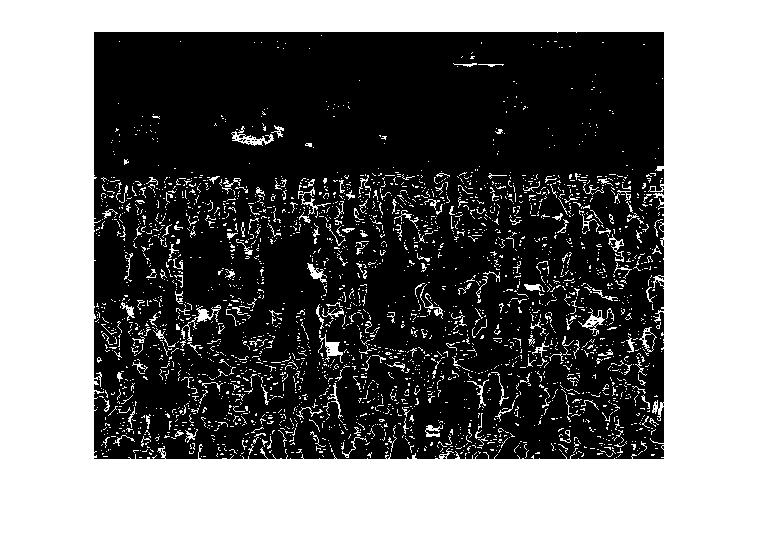

I = imread('Wally.png');
Gray = rgb2gray(I);


I(:,:,1) = medfilt2(I(:,:,1),[1 4]);
I(:,:,2) = medfilt2(I(:,:,2),[1 4]);
I(:,:,3) = medfilt2(I(:,:,3),[1 4]);

J = rgb2hsv(I);

GROC = J(:,:,1) >= 0.125 & J(:,:,1) <= 0.152;
NEGRE = J(:,:,3) < 0.1;

imshow(GROC)

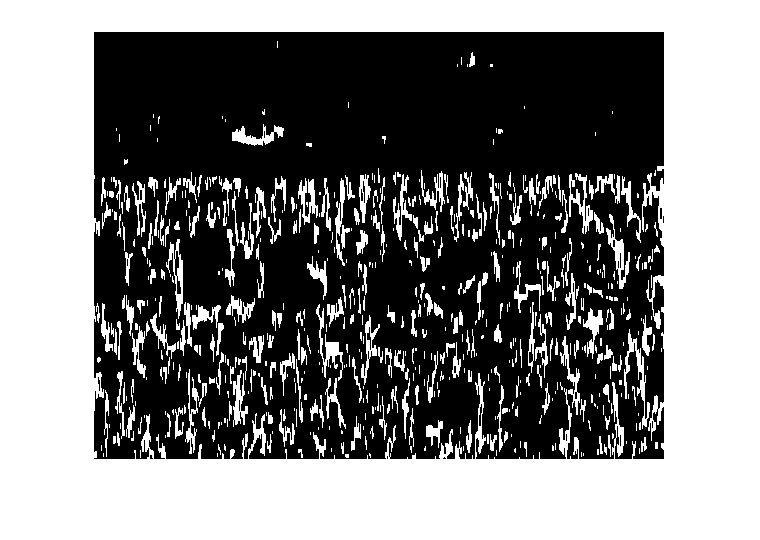


%imshow(G);

SE7 = strel('line',7,90);
SE3 = strel('line',3,90);

disk = fspecial('disk',25);
disk1 = strel('disk',1);

h = fspecial('sobel');
disk = imfilter(disk,h);
disk = abs(disk) > 0;
diskcontorn = imdilate(disk,disk1);
disk = diskcontorn-disk;

GROC = imclose(GROC,SE7);

GROC = imopen(GROC,SE3);

imshow(GROC);

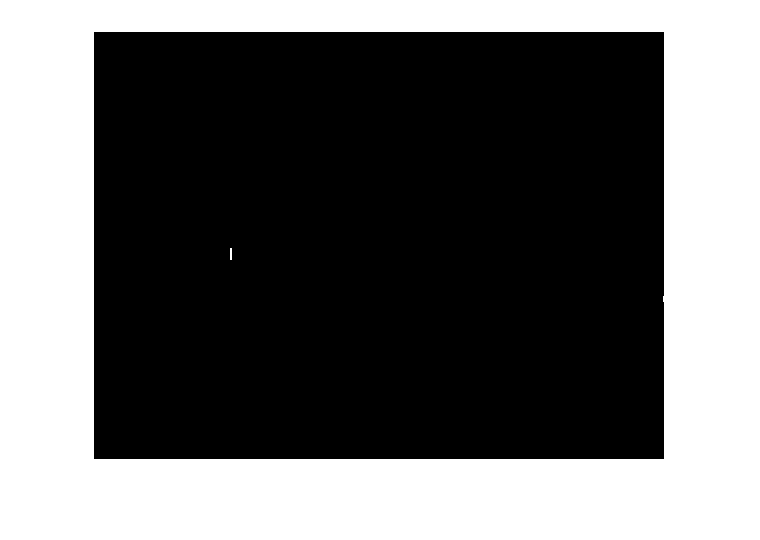


NEGRE = imclose(NEGRE,SE7);
%imshow(NEGRE);
NEGRE = imopen(NEGRE,SE3);
imshow(NEGRE);

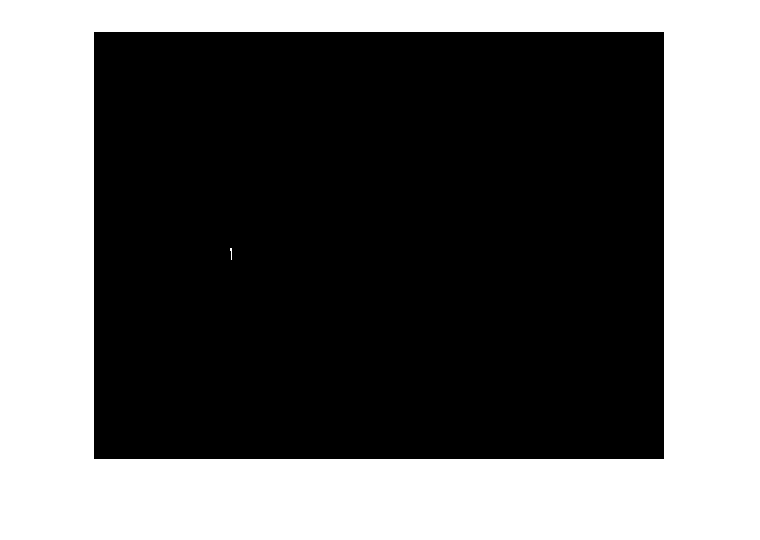


RES = GROC&NEGRE;
imshow(RES);

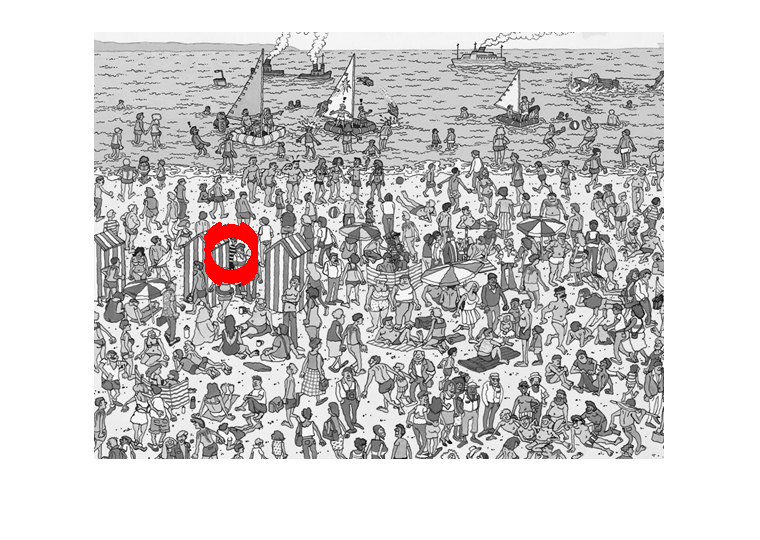

RES = imdilate(RES,disk1);
RES = imdilate(RES,disk);

OL = imoverlay(Gray, RES, 'red');
imshow(OL);